%案例一
i = [900 1000];
j = [900 1000];
v = [10 100];
S = sparse(i,j,v,1500,1500)

S =  (900,900)     10
(1000,1000)   100


%博客案例二
clear all
clc
w=zeros(4);
w(1,2)=2;w(1,3)=3;w(1,4)=8; 
w(2,3)=6;w(2,4)=6;
G=sparse(w)

G =    (1,2)        2
   (1,3)        3
   (2,3)        6
   (1,4)        8
   (2,4)        6


%博客案例三
clear all
clc
%sparse([起点集合],[对应终点集合],[对应权重集合])
G = sparse([3 2 3 4 1],[1 2 2 3 4],[1 2 3 4 5],4,4);
s=sparse(G)

s =    (3,1)        1
   (2,2)        2
   (3,2)        3
   (4,3)        4
   (1,4)        5


%如果是无向图,G=sparse(tril(w'+w)取下三角)

%博客案例四
clear all
clc
W = [.41 .99 .51 .32 .15 .45 .38 .32 .36 .29 .21];
G = sparse([6 1 2 2 3 4 4 5 5 6 1],[2 6 3 5 4 1 6 3 4 3 5],W)

G =    (4,1)       0.4500
   (6,2)       0.4100
   (2,3)       0.5100
   (5,3)       0.3200
   (6,3)       0.2900
   (3,4)       0.1500
   (5,4)       0.3600
   (1,5)       0.2100
   (2,5)       0.3200
   (1,6)       0.9900
   (4,6)       0.3800


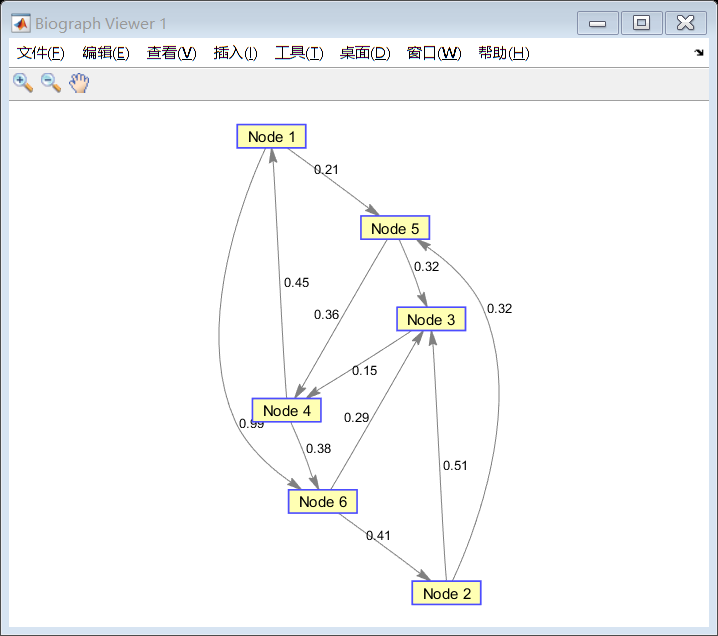

view(biograph(G,[],'ShowWeights','on'))

graphallshortestpaths(G)

ans =          0    1.3600    0.5300    0.5700    0.2100    0.9500
    1.1100         0    0.5100    0.6600    0.3200    1.0400
    0.6000    0.9400         0    0.1500    0.8100    0.5300
    0.4500    0.7900    0.6700         0    0.6600    0.3800
    0.8100    1.1500    0.3200    0.3600         0    0.7400
    0.8900    0.4100    0.2900    0.4400    0.7300         0


%博客案例五
clear all
clc
W = [.41 .99 .51 .32 .15 .45 .38 .32 .36 .29 .21];
G = sparse([6 1 2 2 3 4 4 5 5 6 1],[2 6 3 5 4 1 6 3 4 3 5],W)

G =    (4,1)       0.4500
   (6,2)       0.4100
   (2,3)       0.5100
   (5,3)       0.3200
   (6,3)       0.2900
   (3,4)       0.1500
   (5,4)       0.3600
   (1,5)       0.2100
   (2,5)       0.3200
   (1,6)       0.9900
   (4,6)       0.3800


UG = tril(G + G')

UG =    (4,1)       0.4500
   (5,1)       0.2100
   (6,1)       0.9900
   (3,2)       0.5100
   (5,2)       0.3200
   (6,2)       0.4100
   (4,3)       0.1500
   (5,3)       0.3200
   (6,3)       0.2900
   (5,4)       0.3600
   (6,4)       0.3800


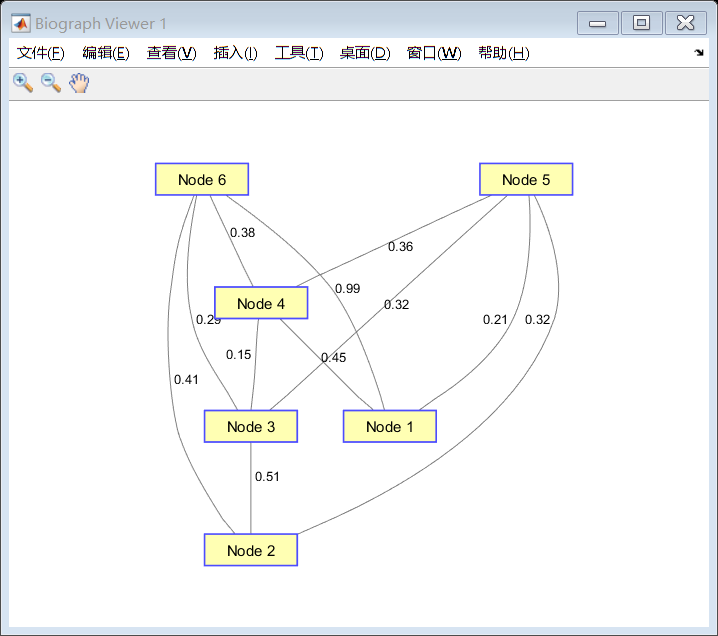

view(biograph(UG,[],'ShowArrows','off','ShowWeights','on'))

graphallshortestpaths(UG,'directed',false)

ans =          0    0.5300    0.5300    0.4500    0.2100    0.8200
    0.5300         0    0.5100    0.6600    0.3200    0.4100
    0.5300    0.5100         0    0.1500    0.3200    0.2900
    0.4500    0.6600    0.1500         0    0.3600    0.3800
    0.2100    0.3200    0.3200    0.3600         0    0.6100
    0.8200    0.4100    0.2900    0.3800    0.6100         0
